clear all;
close all;
clc;

## Generating sample data.

The sx and sy arrays store the location of sensors. 

The ex and ey arrays store the locations of the exictation events.

For now, let's just assign some arbitrary predetermined locations. In the field, these could be assessed manually or via other methods like self configuration achieved through something like ${\textrm{SCSV}}^2$.

sensors = [1 1; 4 5]

sensors =      1     1
     4     5


excitations = [1.5 3.5; 4 2.5]

excitations =     1.5000    3.5000
    4.0000    2.5000


**Sensors **are blue. 

    This means the first sensor, $s_1$, is located at $\left(1,1\right)$. 

    The second sensor, $s_2$, is located at the point $\left(4,5\right)$. 

**Excitations** are orange.

    The location of the first excitation, $e_1$, is at $\left(1\ldotp 5,3\ldotp 5\right)$.

    The location of the second excitation, $e_2$ is at $\left(4,2\ldotp 5\right)$.

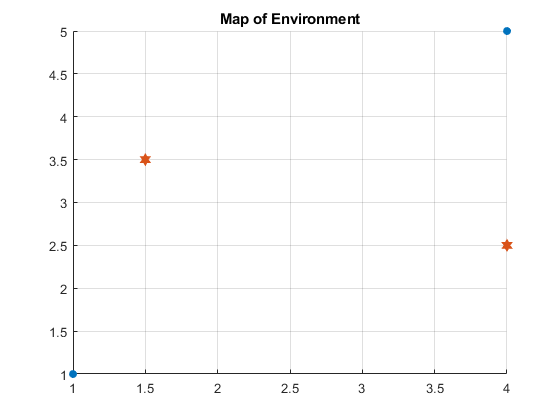

scatter(sensors(:,1), sensors(:,2), 'filled'); % Location of sensors
grid on;
title("Map of Environment");

hold on;
scatter(excitations(:,1), excitations(:,2), 100, 'filled', 'hexagram'); % Location of excitation
hold off;

We might as well find out what the distance between each sensor and an excitation in order for later use in estimating time synchronization delay using wave propogation.

Next, we need some sensor data. The **Mexican hat wavelet** is chosen as the mother wavelet as it is a good representation of the footstep-induced vibration signals due to its similarity in shape. 

There's a few methods that MATLAB provides for generating a Mexican hat wavelet, but the one I chose was the `wavefun` command, which outputs a $\psi$ and an xval. 

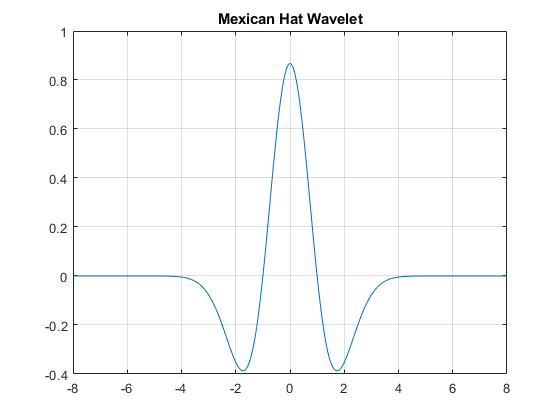

% See https://www.mathworks.com/help/wavelet/ref/waveinfo.html 
% and also https://www.mathworks.com/help/wavelet/ref/wavefun.html

[psi,xval] = wavefun('mexh',10);
plot(xval,psi);
grid on;
title(['Mexican Hat Wavelet']);


% See also https://www.mathworks.com/help/wavelet/ref/mexihat.html

That aforementioned $\psi$ can be given Gaussian noise via the `awgn` function provided by MATLAB.

The acronym `awgn` stands for "**Add white Gaussian noise**".

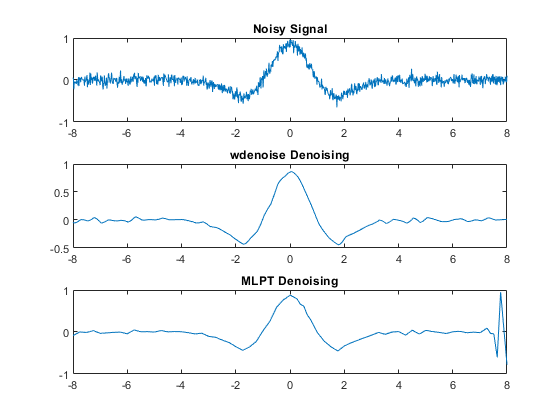

noisy = awgn(psi,10,'measured');
subplot(3,1,1);
plot(xval,noisy);
title(['Noisy Signal']);

denoised = wdenoise(noisy,4);
subplot(3,1,2);
plot(xval, denoised);
title(['wdenoise Denoising']);

% https://www.mathworks.com/help/wavelet/examples/smoothing-nonuniformly-sampled-data.html
denoised2 = mlptdenoise(noisy,xval,4);
subplot(3,1,3);
plot(xval, denoised2);
title(['MLPT Denoising']);
hold off;

I used `wdenoise` to denoise the noise we just gave it. As you can see, there are still some artifacts leftover. I am not sure what to do about this. 

The third plot you see is using MLPT denoising, which is done to preserve the impulses we might see in actual signals, which would indicate a vibration excitation, and thus should not be smoothed out. This is the method I am thinking of going with for the future. 